# **Project**

clear; close all; clc;
set(groot,'defaulttextinterpreter','Latex');
set(groot, 'defaultAxesTickLabelInterpreter','Latex');
set(groot, 'defaultLegendInterpreter','Latex');

## Preliminary

#### Constant Introduction

Var.lstar = 385692.5;                           % Characteristic length, km
Var.tstar = 377084.1526670386;                  % Characteristic time, s
Var.vstar = Var.lstar / Var.tstar;              % Characteristic velocity, km/s

Var.m1 = 398600.4328969393;                     % Gravitational parameter of Earth
Var.m2 = 4902.800582147765;                     % Gravitational parameter of Moon
Var.rEL = 384400;                               % Distance between Earth and Moon, nondim

Var.mstar = Var.m1 + Var.m2;

Var.R1 = 6378;                                  % Radius of Earth, km
Var.R2 = 1737;                                  % Radius of Moon, km

Var.n = sqrt(Var.m1 / Var.rEL^3);               % Mean motion of Moon
Var.D1 = Var.m2 * Var.rEL / (Var.m1 + Var.m2);
Var.mu = Var.m2 / (Var.m1 + Var.m2);

Var.vecSize = 5000;                             % Attitude representation vector length, km

Var.L2x = L2LagrangePoint(Var.mu);              % L2 Lagrange Point (x)

Var.OrbFam = 300;                              % Orbit Family # (the higher the more eccentric)

% S/C Parameter

%Var.J = diag([1,1,3/2]);                        % Moment of Inertia
%Var.K = JtoK(Var.J);

Var.J = [67946 -82 11129; -83 90061 103; 11129 103 45821] / ((Var.lstar/1000)^2 * ((Var.m1 + Var.m2)));    % Moment of Inertia (nondim)

Var.m = 6200 / (Var.m1 + Var.m2);                % Spacecraft mass (nondim)

Var.I = [Var.J zeros(3); zeros(3) Var.m*eye(3)];


#### Variable Introduction

Var.NumOrb = 1;                                 % Number of orbits to propagate

Var.tol = 1e-12;                                % Numerical Integration Tolerance
opt = odeset('Reltol', Var.tol,'Abstol', Var.tol);

Var.N = 32;                                     % MPC Window Step
N = Var.N;

## Reference State History

Reference state is calculated from $x=\left\lbrack \begin{array}{cccccc}
x & y & z & \dot{x}  & \dot{y}  & \dot{z} 
\end{array}\right\rbrack$. Since it's just a reference, $\mathit{\mathbf{u}}=0\;\forall \;t$. 

% Southern Halo
load('Shaloorbits.mat');

ref_orb = x_Halo2{10};

init_ref = ref_orb(1,1:6)';               % Initial Trajectory [x y z xdot ydot zdot]_0

X = ode45(@(t,X) StateSTMdot(t, X, Var.mu),[0 (Var.NumOrb+1)*ref_orb(end,end)], [init_ref; reshape(eye(6), [], 1)], opt);

Evaluate at $t$ with constant time-step, which easily discretizes. There are two options to define $t$: 1) define step-size, 2) define size of $t$ vector.

Since $N=32$, $30N$ points would be enough.

%t = 0:1e-3:x_Halo2{1500}(end,end)


%window_time = ref_orb(end,end)/size(ref_orb,1)/N;
window_time = ref_orb(end,end)/N/30

window_time = 0.0018

T = window_time / N

T = 2.7679e-05

t = 0:T:ref_orb(end,end); t=t';
t = linspace(0,ref_orb(end,end),20*N)';
T = t(2)-t(1)

T = 0.0027

%T = t(2)-t(1);

%t = ref_orb(:,end);
%window_time = ref_orb(end,end)/size(ref_orb,1)/N;
%T = window_time/N

X_ref = deval(X, t);


pos_ref = X_ref(1:3,:);                             % Reference position history
pos_ref = [pos_ref(:,1) repmat(pos_ref(:,2:end), 1, Var.NumOrb)]; 
vel_ref = X_ref(4:6,:);                             % Reference velocity history
vel_ref = [vel_ref(:,1) repmat(vel_ref(:,2:end), 1, Var.NumOrb)]; 
STM_ref = reshape(X_ref(7:end,:), 6,6,size(X_ref,2));   % Reference STM history



For the attitude, have constant one for now:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Reference Attitude %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
att_ref = eye(3);                               % Reference (constant) attitude, DCM

%{
for i = 1:size(X,2)                             
    att_ref(:,:,i) = eye(3);                        
end                              
%}

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Reference Ang. Vel %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
omg_ref = zeros(3,size(vel_ref,2));                   % Reference angular velocity 
                                               

Convert to SE(3) state variable representation and repeat for Var.NumOrb:

g_ref = []; v_ref = [omg_ref; vel_ref];

for i = 1:size(t)
    g_ref(:,:,i) = SE3(att_ref, pos_ref(:,i));
end

Using cat: concatenate in 3D direction; start with initial condition but repeat from second index to end in order to avoid duplicate state at end which is the same as the first index of the succeeding matrix. Just in case, increase the number of orbits by one.

g_ref = cat(3, g_ref(:,:,1), repmat(g_ref(:,:,2:end), 1, 1, Var.NumOrb+1));
v_ref = [v_ref(:,1) repmat(v_ref(:,2:end), 1, Var.NumOrb+1)];

Now $g^0 \left(k\right)$ and $v^0 \left(k\right)$ are ready.

Check the plot of the reference trajectory

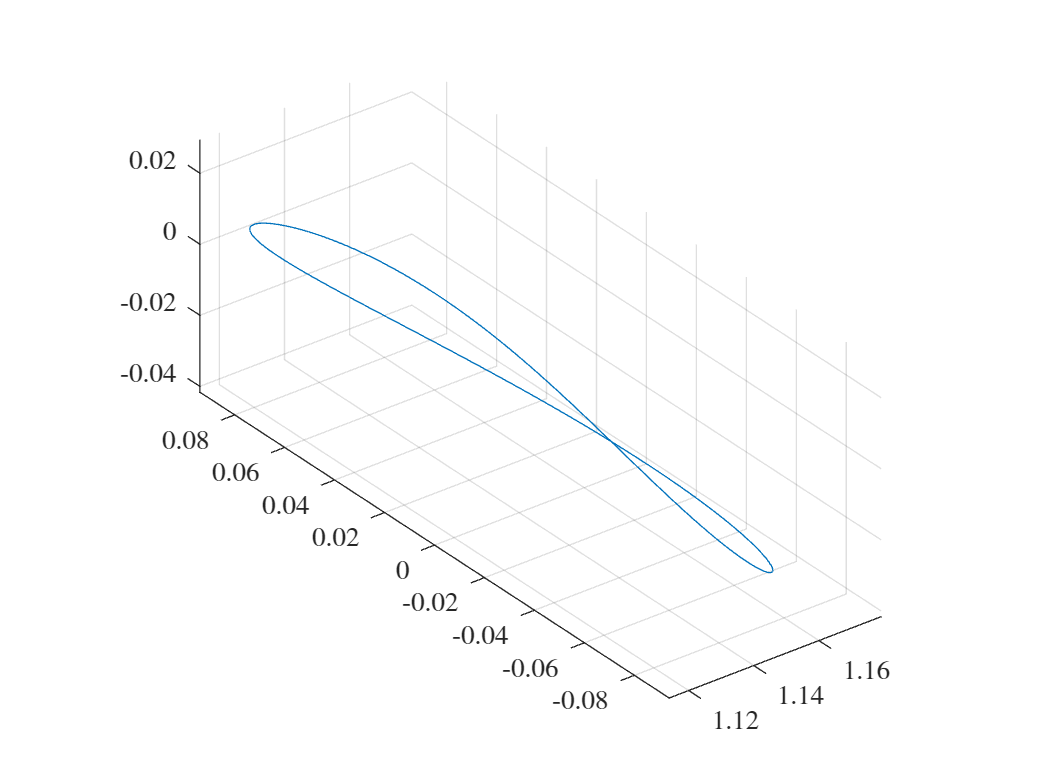

%
figure()
plot3(pos_ref(1,:), pos_ref(2,:), pos_ref(3,:)); grid
axis equal



figure()
plot3(squeeze(g_ref(1,4,:)),squeeze(g_ref(2,4,:)),squeeze(g_ref(3,4,:))); grid
axis equal

%}

## Spacecraft Initial Condition (Chief)


[C0, ~] = EAtoDCM([pi/4 -3*pi/2 pi/6],[1 2 3]);
%C0 = att_ref;                                   % Initial C = [SB]
R0 = pos_ref(:,1);                              % Initial position in synodic frame
nu0 = vel_ref(:,1);                             % Initial velocity in synodic frame

w0 = [pi/4 -pi/3 pi/6]';
%w0 = omg_ref(:,1);                              % Initial angular velocity in synodic frame

g0 = SE3(C0, R0);
v0 = [w0; nu0];


### Relative State 

May develop further into incorporating exp(SE(3)) error dynamics

dC0 = att_ref' * C0;
dR0 = att_ref' * (R0 - pos_ref(:,1));

dg0_inv = SE3(C0' * att_ref, C0' * (pos_ref(:,1) - R0));

dg0 = SE3(dC0, dR0);
dv0 = v0 - AdSE3(dg0_inv) * [0; 0; 0; vel_ref(:,1)];   

## Spacecraft (deputy "a")

a_orb = x_Halo2{100};

init_ref_a = a_orb(1,1:6)';

[C0a, ~] = EAtoDCM([pi/4 -3*pi/2 pi/6],[1 2 3]);
%C0a = eye(3);
R0a =  init_ref_a(1:3);   

w0a = [0 0 0]';
nu0a = init_ref_a(4:6);

g0a = SE3(C0a, R0a);
v0a = [w0a; nu0a];

## Uncontrolled Behavior with SE(3)


t2end = t(2:end);
for i = 1:Var.NumOrb-1
    t = [t; t2end+t(end)];
end

X6 = deval(X, t);
pos_x6 = X6(1:3,:);

init = [reshape(g0,[],1);v0];
X = ode45(@(t,X)SE3CR3BP(t, X, Var.I, Var.mu, [0 0 0 0 0 0]'), [0 t(end)], init, opt);

inita = [reshape(g0a,[],1);v0a];
Xa = ode45(@(t,X)SE3CR3BP(t, X, Var.I, Var.mu, [0 0 0 0 0 0]'), [0 t(end)], inita, opt);

Analysis

X = deval(X, t);
Xa = deval(Xa, t);

for i = 1:length(t)
    g(:,:,i) = reshape(X(1:16,i),4,4);
    [~, temp] = invSE3(g(:,:,i));
    r(:,i) = temp;
    v(:,i) = X(17:22);

    ga(:,:,i) = reshape(Xa(1:16,i),4,4);
    [~, temp] = invSE3(ga(:,:,i));
    ra(:,i) = temp;
    va(:,i) = Xa(17:22);

    g_ca(:,:,i) = ga(:,:,i)\g(:,:,i);
    
end

figure()
plot3(pos_ref(1,:), pos_ref(2,:), pos_ref(3,:),'o'); grid; hold

Current plot held


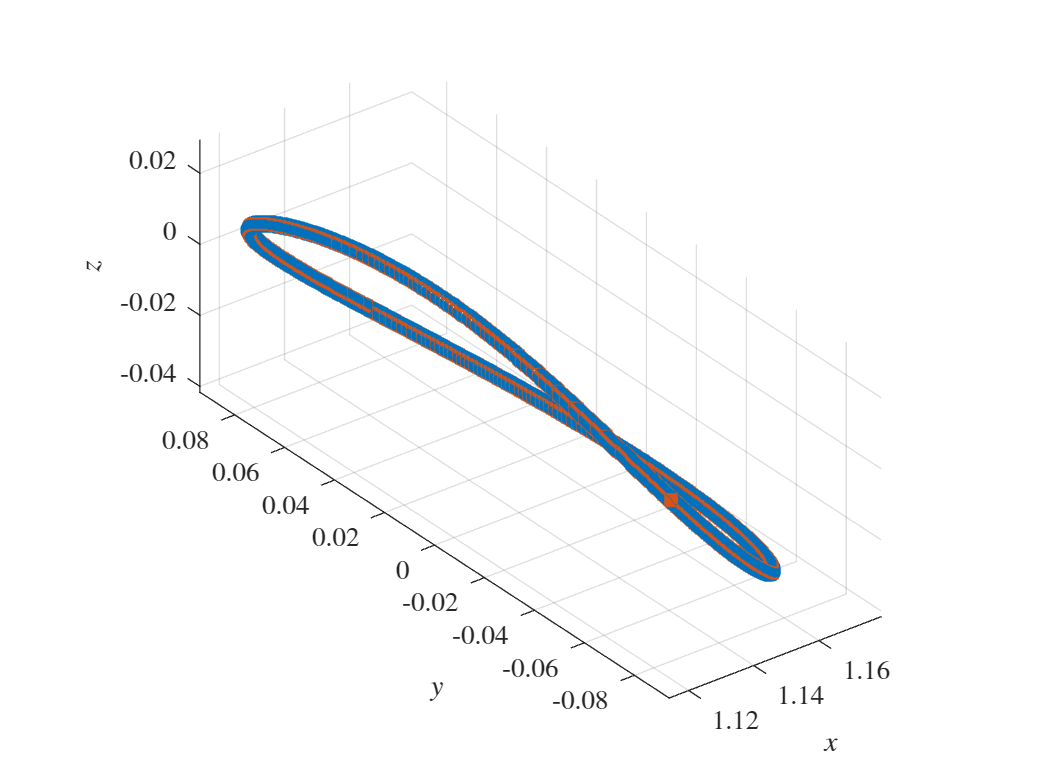

plot3(r(1,:), r(2,:), r(3,:), 'square')
axis equal
xlabel('$x$')
ylabel('$y$')
zlabel('$z$')


%{
figure()
plot3(r(1,:), r(2,:), r(3,:)); grid; hold
plot3(pos_x6(1,:), pos_x6(2,:), pos_x6(3,:),'--')
axis equal
legend('SE(3) Variable', 'Position/Velocity State')
xlabel('$x$')
ylabel('$y$')
zlabel('$z$')

figure()
plot(t, r(1,:)-pos_ref(1,:)); grid; hold
plot(t, r(2,:)-pos_ref(2,:));
plot(t, r(3,:)-pos_ref(3,:));
plot(t, pos_x6(1,:)-pos_ref(1,:), '--');
plot(t, pos_x6(2,:)-pos_ref(2,:), '--');
plot(t, pos_x6(3,:)-pos_ref(3,:), '--');

for i = 1:length(t)
    normSE3(i) = norm(r(:,i) - pos_ref(:,i));
    normx6(i) = norm(pos_x6(:,i) - pos_ref(:,i));
end
figure()
plot(t, normSE3); hold; grid
plot(t, normx6, '--')
legend('SE(3) Variable', 'Position/Velocity State')
xlabel('$t$')
ylabel('Error')
hold off
%}

%{
figure()
plot3(r(1,:), r(2,:), r(3,:)); grid; hold
plot3(ra(1,:), ra(2,:), ra(3,:))
for i = linspace(1, length(r), 10)
    DrawAttitude(floor(i), g, Var, 'cl')
end
for i = linspace(1, length(ra), 10)
    DrawAttitude(floor(i), ga, Var, 'bl')
end
legend('Chief', 'Deputy a')
xlabel('$x$')
ylabel('$y$')
zlabel('$z$')
%}

## Error dynamics based propagation

Now, set synodic frame as the reference (chief) and the spacecraft to be deputy. It's just an error dynamics, doesn't necessarily makes it go 0.


$$g_s \left(t\right)=\left\lbrack \begin{array}{cccc}
\cos \;\textrm{nt} & \sin \;\textrm{nt} & 0 & 0\\
-\sin \;\textrm{nt} & \cos \;\textrm{nt} & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack ,v_s \left(t\right)=\vec{0}$$


%{
% FOR ERROR DYNAMICS TEST
%C0 = att_ref;                                   % Initial C = [SB]
[C0,~] = EAtoDCM([pi/4 -pi/5 3*pi/2], [1,2,3])
R0 = pos_ref(:,1);                              % Initial position
nu0 = vel_ref(:,1);                             % Initial velocity

w0 = [0 0 0]';
%w0 = omg_ref(:,1);                              % Initial angular velocity

%C0 =eye(3);
g0 = SE3(C0, R0)
v0 = [w0; nu0];
%}

eta0 = logSE3(g0)

eta0 =    -2.5789
   -3.3609
   -2.5789
   -0.0054
    0.6994
    0.2313


%}


## CasADi for Nonlinear Control

%
addpath('casadi-windows-matlabR2016a-v3.5.5');
import casadi.*

Define states using CasADi symbolic

x = SX.sym('x'); y = SX.sym('y'); z = SX.sym('z');
C11 = SX.sym('C11'); C12 = SX.sym('C12'); C13 = SX.sym('C13');
C21 = SX.sym('C21'); C22 = SX.sym('C22'); C23 = SX.sym('C23');
C31 = SX.sym('C31'); C32 = SX.sym('C32'); C33 = SX.sym('C33');
%states = SE3([C11 C12 C13; C21 C22 C23; C31 C32 C33], [x;y;z]);
states = [C11 C12 C13 C21 C22 C23 C31 C32 C33 x y z]';
n_states = length(states);
wx = SX.sym('wx'); wy = SX.sym('wy'); wz = SX.sym('wz');
vx = SX.sym('vx'); vy = SX.sym('vy'); vz = SX.sym('vz');
vels = [wx wy wz vx vy vz]';
n_vels = length(vels);

Define control: tau and thrust

tx = SX.sym('tx'); ty = SX.sym('ty'); tz = SX.sym('tz');
fx = SX.sym('fx'); fy = SX.sym('fy'); fz = SX.sym('fz');
controls = [tx ty tz fx fy fz]';
n_controls = length(controls);

### Max Control Input Constraint

Var.fmax = 1/1000*Var.tstar^2/(Var.mstar*Var.lstar);           % Maximum orbital control input, 1 newton
Var.taumax = 1/1000*Var.tstar^2/(Var.mstar*Var.lstar)*1e-3;    % Maximum attitude control input, 1 milli-newton

### Parameters, used for function

P is for g

D is for velocity

% additional spacecrafts here, or just one for chief spacecraft

P = SX.sym('P', n_states, N+7); % Parameters of initial and desired states
D = SX.sym('D', n_vels, N+7);   %              "                 vels


#### Dynamics

[statedot, cstatedot] = SE3CasADiDynamics(states, vels, controls, Var);
% Pack above function into CasADi symbolic function 'f'.
f = Function('f', {states,vels,controls}, {statedot, cstatedot});

### Variable storage

Control block over control window: U

U = SX.sym('U', n_controls, N); 


Prediction block: X for state and V for velocity

X = SX.sym('X', n_states, (N+1));   % Complete State Matrix
V = SX.sym('V', n_vels, (N+1));     % Complete vel Matrix

We want the initial state to be matching between the actual and desired (can't start with different)

X(:,1) = P(:,1);                    % Set initial state
V(:,1) = D(:,1);                    % Set initial vel

### State Integration with 4th Order Runge-Kutta 

for k = 1:N
    st = X(:,k);    % current state
    vl = V(:,k);   % current vel
    con = U(:,k);   % current control

    [k1,l1] = f(st, vl, con);                   % new 
    [k2,l2] = f(st + T/2*k1, vl + T/2*l1, con); % new
    [k3,l3] = f(st + T/2*k2, vl + T/2*l2, con); % new
    [k4,l4] = f(st + T*k3, vl + T*l3, con);     % new
    
    st_next = st + T/6*(k1 + 2*k2 + 2*k3 + k4);     % new state
    vl_next = vl + T/6*(l1 + 2*l2 + 2*l3 + l4);   % new vel
    X(:,k+1) = st_next;
    V(:,k+1) = vl_next;
end

ff = Function('ff', {U,[P;D]}, {X,V});

### Cost function

Q = 100;
%Q = 10000*eye(16);
R = diag([1,1,1,10,10,10]);

obj = 0;
for k = 1:N
    % Add stage cost
    st_c = X(:,k);
    st = SE3(reshape(st_c(1:9), 3, 3), st_c(10:12)); % State, g
    
    % Reminder: P is the reference states
    p_c = P(:,k);
    p_test = SE3(reshape(p_c(1:9), 3, 3), p_c(10:12)); % Desired state, g0

    SB_e = reshape(p_c(1:9),3,3)' * reshape(st_c(1:9),3,3);
    R_e = p_c(10:12) - st_c(10:12);
    
    %h = SE3(SB_e, R_e);

    con = U(:,k);

    h = p_test\st;
    
    obj = obj + Q*norm((h - eye(4)), 'fro')^2 + con' * R * con;
    %obj = obj + sum(h - eye(4)) + con' * R * con;
end

st_c = X(:,N+1);      
st = SE3(reshape(st_c(1:9), 3, 3), st_c(10:12));

p_c = P(:,N+1);
p_test = SE3(reshape(p_c(1:9), 3, 3), p_c(10:12));

%h = SE3(SB_e, R_e);
h = p_test\st;

SB_e = reshape(p_c(1:9),3,3)' * reshape(st_c(1:9),3,3);
R_e = p_c(10:12) - st_c(10:12);

%h = SE3(SB_e, R_e);

obj = obj + Q*norm((h - eye(4)), 'fro')^2;

%obj = obj + sum(h - eye(4));

%obj = obj + 1/2 * vh'*Q*vh;


### Constraint

args = struct;
cst = [];

path <= constraint; domain: (-inf, 0)

args.lbg = -inf;
args.ubg = 0;

Input constraint

args.lbx = -inf;
args.ubx = inf;

for k = 1:N+1
    if k <= N
        cst = [cst; U(4,k)^2+U(5,k)^2+U(6,k)^2 - Var.fmax^2];   
        cst = [cst; U(1,k)^2+U(2,k)^2+U(3,k)^2 - Var.taumax^2];   
    else
        cst = [cst; 0];
    end
end

## NMPC Setup

Complete transition function: given control and parameter value, yield X and V 



%g0 = g_ref(:,:,1);     % Initial state
initpert = [0.0002 -0.0008 -0.0004]'; % Init pert
C0 = EAtoDCM([3*pi/2 -5*pi/3 pi/2], [2,1,3]);
g0 = SE3(C0, g_ref(1:3,4,1));
%v0 = v_ref(:,1);       % Initial velocities

w0 = 10*[pi/4 -pi/2 3*pi/2]';
v0 = [w0; nu0];% + [-0.0003 0.0001 0.0007 0.0005 -0.0007 0.0003]';


v0u = v0;
g0u = g0;

t0 = 0;
xx_uncontrol(:,:,1) = g0u; % xx_uncontrol is the history of uncontrolled states
vv_uncontrol(:,1) = v0u; % vv_uncontrol is the history of uncontrolled velocities
xx(:,:,1) = g0;     % xx is the history of states
vv(:,1) = v0;       % vv is the history of velocities
t_MPC(1) = 0;          % Setting the initial time vector to t0
u0 = zeros(N,6);    % Six control inputs
mpciter = 0;        % Interation number of the mpc
xx1 = [];           % Temporary state variable storage
vv1 = [];           % Temporary velocity variable storage
u_cl = [];          % Temporary control variable storage

OPT_variables = reshape(U, n_controls*N, 1); % Variable to optimize: input
nlp_prob = struct('f', obj, 'x', OPT_variables, 'g', cst, 'p', [P;D]);


#### Solver option

opts = struct;
opts.ipopt.max_iter = 100;
opts.ipopt.print_level = 0;
opts.print_time = 0;
opts.ipopt.acceptable_tol = Var.tol;
opts.ipopt.acceptable_obj_change_tol = Var.tol;
solver = nlpsol('solver', 'ipopt', nlp_prob, opts); % ipopt is interior point



## NMPC Loop

wb = waitbar(0, "preparing...");
tic
while mpciter < length(t)


#### Gaussian Perturbation

    %p2 = zeros(6,1);        % Perturbation on velocities
    rot_pert = 0.003*randn(3,1);
    trs_pert = 0.008*randn(3,1);
    p2 = [rot_pert; trs_pert];
    v0 = v0 + p2 * T;       % Perturbation over step added
    v0u = v0u + p2 * T;

  

### Parameter vector setup

Parameter vector has a structure of [init, ref(2), ref(3), ..., ref(N)]

    args.p = LinST(g0);
    for i = mpciter+1:mpciter+N+6
        args.p(:,i-mpciter+1) = LinST(g_ref(:,:,i+1));
    end
    args.p = [args.p; v0 v_ref(:,mpciter+2:mpciter+N+7)];

    % Maybe add rows on parameter vector for the additional spacecraft
    % pose?
    

### Optimal Control Solve

    args.x0 = reshape(u0, 6*N, 1);      % Initial value of the optimization variables
    sol = solver('x0', args.x0, 'lbx', args.lbx, 'ubx', args.ubx, 'lbg', ...
        args.lbg, 'ubg', args.ubg, 'p', args.p);

    u = reshape(full(sol.x)', 6, N)';

#### Propagation

    [ff_value1, ff_value2] = ff(u', args.p);
    
    % Data storage
    xx1(:,1:12,mpciter+1) = full(ff_value1)';   % Predicting Window
    vv1(:,1:6,mpciter+1) = full(ff_value2)';    %          "      
    uu1(:,1:6,mpciter+1) = u;
    u_cl = [u_cl; u(1,:)];

    t_MPC(mpciter+2) = t0;
    [t0,g0,v0,u0] = shiftCL(T, t_MPC(mpciter+2), LinST(g0), v0, u, f);
    g0 = SE3(reshape(g0(1:9),3,3), g0(10:12));
    xx(:,:,mpciter+2) = g0;
    vv(:,mpciter+2) = v0;

    %% uncontrolled
    [~,g0u,v0u,~] = shiftCL(T, t_MPC(mpciter+2), LinST(g0u), v0u, zeros(size(u)), f);
    g0u = SE3(reshape(g0u(1:9),3,3), g0u(10:12));
    xx_uncontrol(:,:,mpciter+2) = g0u;
    vv_uncontrol(:,mpciter+2) = v0u;

    %{
    figure()
        grid; hold
        %plot3(pos_ref(1,:), pos_ref(2,:), pos_ref(3,:))
        %plot3(squeeze(g_ref(1,4,mpciter+1:mpciter+N+6)),...
        %    squeeze(g_ref(2,4,mpciter+1:mpciter+N+6)),...
        %    squeeze(g_ref(3,4,mpciter+1:mpciter+N+6))); 
        %plot3(g0(1,4), g0(2,4), g0(3,4), 'o')
        plot3(xx1(:,10), xx1(:,11), xx1(:,12), 'g-')
        campos([1.2,-0.1,0.1])
        axis equal
    %}

#### Progressive Update

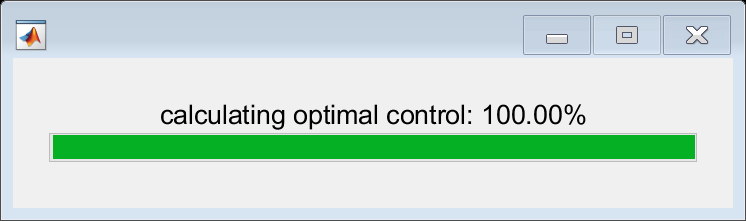


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit http://projects.coin-or.org/Ipopt
******************************************************************************

CasADi -  WARNING("solver:nlp_f failed: NaN detected for output f, at (row 1, col 1).") [.../casadi/core/oracle_function.cpp:265]
CasADi -  WARNING("solver:nlp_f failed: NaN detected for output f, at (row 1, col 1).") [.../casadi/core/oracle_function.cpp:265]
CasADi -  WARNING("solver:nlp_f failed: NaN detected for output f, at (row 1, col 1).") [.../casadi/core/oracle_function.cpp:265]
CasADi -  WARNING("solver:nlp_f failed: NaN detected for output f, at (row 1, col 1).") [.../casadi/core/oracle_function.cpp:265]
CasADi -  WARNING("solver:nlp_f failed: NaN detected for output f, at (row 1, col 1).") [...

    mpciter = mpciter + 1;
    waitbar(mpciter / (length(t)), wb, ...
        sprintf("calculating optimal control: %.2f%%", ...
        100*mpciter / length(t)));
    
end

toc

Elapsed time is 25199.277102 seconds.


## CasADi NMPC Analysis

%% MPC Result Analysis
U_tau = u_cl(:,1:3);
U_f = u_cl(:,3:6);

for i = 1:size(xx,3)
    [SB_mpc(:,:,i), R_mpc(:,i)] = invSE3(xx(:,:,i));
    [SB_noc(:,:,i), R_noc(:,i)] = invSE3(xx_uncontrol(:,:,i));
end


### Figureworks

3D Visualization

figure()
hold; grid

Current plot held


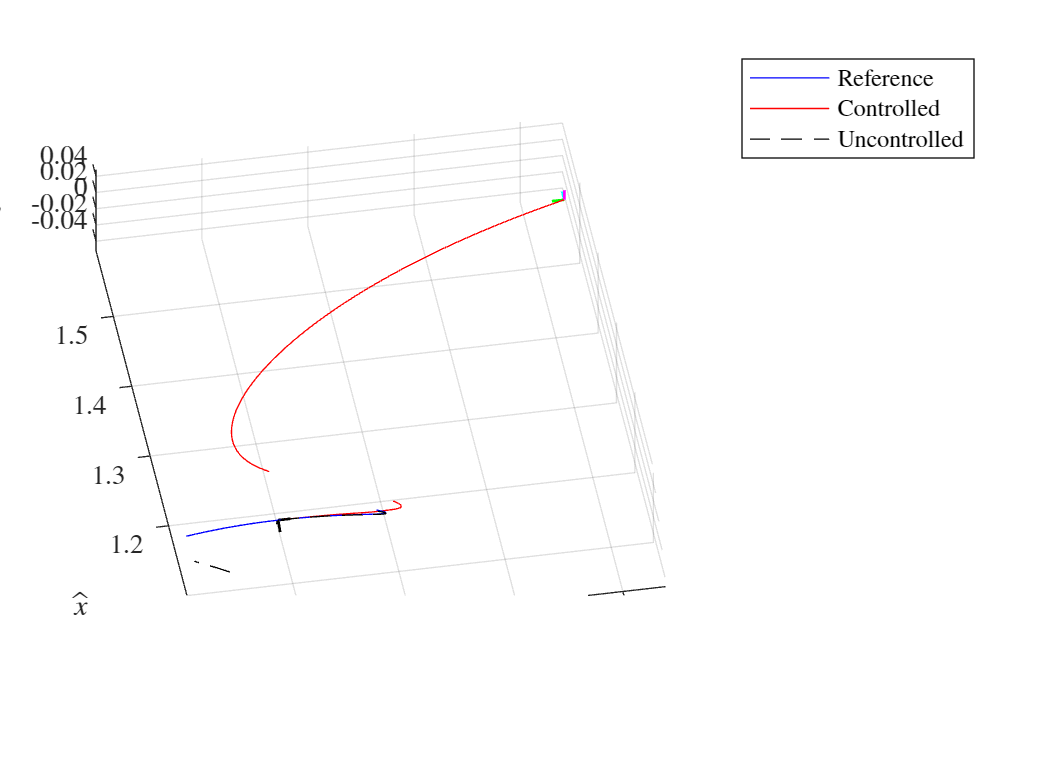

plot3(pos_ref(1,:), pos_ref(2,:), pos_ref(3,:), 'b-')
plot3(R_mpc(1,:), R_mpc(2,:), R_mpc(3,:), 'r-')
plot3(R_noc(1,:), R_noc(2,:), R_noc(3,:), 'k--')
for i = linspace(1, length(R_mpc), 3)
    DrawAttitude(floor(i), xx, Var, 'cl')
end
for i = linspace(1, length(R_noc), 3)
    DrawAttitude(floor(i), xx_uncontrol, Var, 'bl')
end
campos([1.2,-0.1,0.1])

axis equal
legend('Reference', 'Controlled', 'Uncontrolled')
xlabel('$\hat x$')
ylabel('$\hat y$')
zlabel('$\hat z$')

Error History

Input History

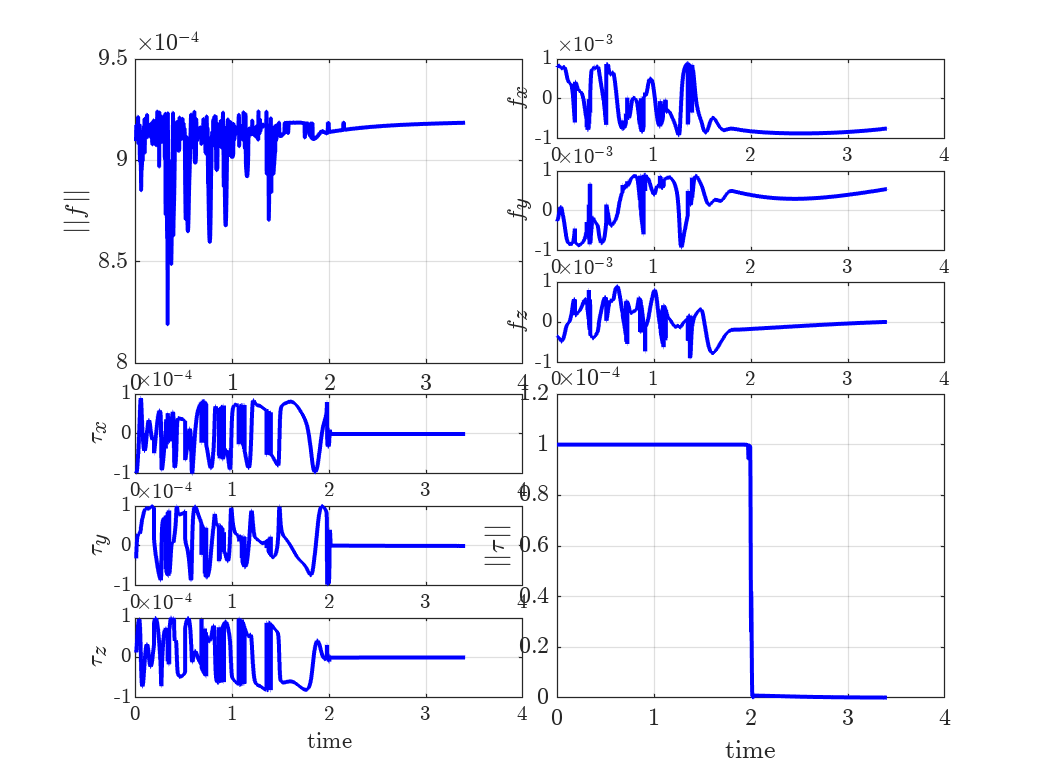

tau_mag = sqrt(u_cl(:,1).^2 + u_cl(:,2).^2 + u_cl(:,3).^2);
f_mag = sqrt(u_cl(:,4).^2 + u_cl(:,5).^2 + u_cl(:,6).^2);

figure()
subplot(6,6,[1:3 7:9 13:15])
plot(t, f_mag, 'b', 'linewidth', 1.5); grid         % Change to stairs?
ylabel('$||f||$')
subplot(6,6,4:6)
stairs(t,u_cl(:,4),'b','linewidth',1.5); grid
ylabel('$f_x$')
subplot(6,6,10:12)
stairs(t,u_cl(:,5),'b','linewidth',1.5); grid
ylabel('$f_y$')
subplot(6,6,16:18)
stairs(t,u_cl(:,6),'b','linewidth',1.5); grid
ylabel('$f_z$');
subplot(6,6,19:21)
stairs(t,u_cl(:,1),'b','linewidth',1.5); grid
ylabel('$\tau_x$')
subplot(6,6,25:27)
stairs(t,u_cl(:,2),'b','linewidth',1.5); grid 
ylabel('$\tau_y$')
subplot(6,6,31:33)
stairs(t,u_cl(:,3),'b','linewidth',1.5); grid
ylabel('$\tau_z$')
xlabel('time')
subplot(6,6,[22:24 28:30 34:36])
plot(t, tau_mag, 'b', 'linewidth', 1.5); grid         % Change to stairs?
ylabel('$||\tau||$')
xlabel('time')

### A

### nimation

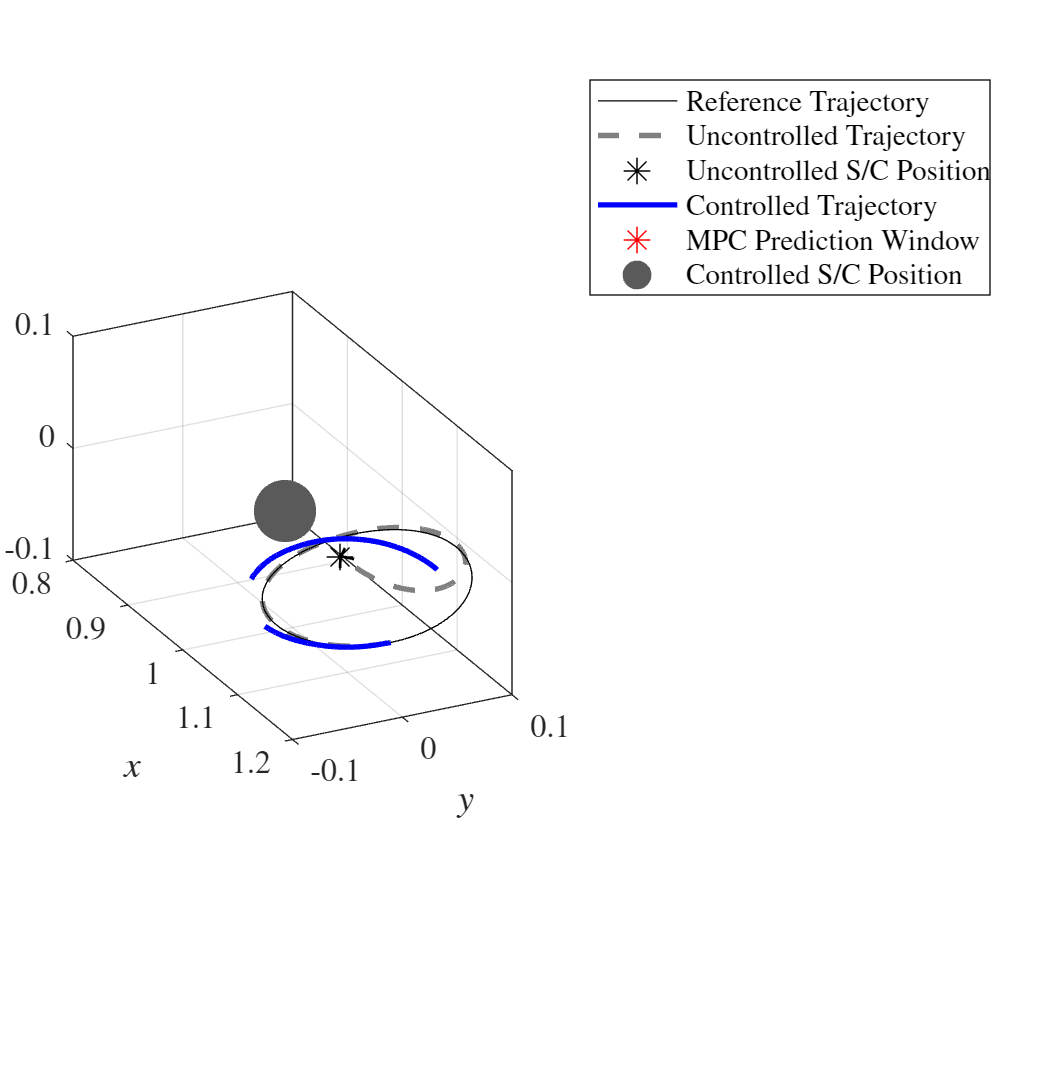

draw_video_CasADi(xx,xx1,xx_uncontrol,N,g_ref, Var)

%}

## Convex Optimization; CMPC

## MPC

%{
wb = waitbar(0, "Preparing...");
tic                                             % Elapsed time

Propagate until $t\left(k-1\right)$ 

while(mpciter < length(t)-1)    

### Target Identification

### Dynamics

#### Simple Perturbation

    %{
    rot_pert = 0.001 * randn(3,1);
    trs_pert = 0.005 * randn(3,1);

    v0 = v0 + [rot_pert; trs_pert];
    %}

We have the following original nonlinear equations of motions for the SE(3) state variables:


$$\dot{g} ={\textrm{gv}}^{\wedge }$$



$$\dot{v} =I^{-1} \left({\textrm{ad}}_v^* \textrm{Iv}+\phi_g +u+u_d \right)$$


where $\phi_g ={\left\lbrack \begin{array}{cc}
M_g^T  & F_g^T 
\end{array}\right\rbrack }^T$ and $u_d$ is modelled as perturbation.

#### Error Dynamics

We can rewrite the above equations in terms of error, or the difference between the actual and reference state:

#### Linearized System Dynamics

The system is Nonlinear, time-invariant; thus the system can be linearized to create LTI model. One benefit of using MPC is that the propagation time ($N=32$) is short enough and the nominal point changes every step, along the propagation.

Following $A$ and $B$ gives $x\left\lbrack k+1\right\rbrack =e^{\textrm{AT}} x\left\lbrack k\right\rbrack +A^{-1} \left(e^{\textrm{AT}} -I\right)\textrm{Bu}\left\lbrack k\right\rbrack$

$\delta x\left(k+1\right)=A\delta x\left(k\right)+B\delta u\left(k\right)$ where $\delta x=x-x^0$ and $\delta u=u-u^0 =u$. Therefore, $x\left(k+1\right)=A\left(x\left(k\right)\right)\left\lbrack x\left(k\right)-x^0 \left(k\right)\right\rbrack +Bu\left(k\right)+x\left(k\right)$. 

    [c, r] = invSE3(dg0);
    A = Af(Var.J(1,1),Var.J(2,2),Var.J(3,3),...
        Var.mu, dv0(1), dv0(2), dv0(3),...
        r(1), r(2), r(3));
    B = Bf();

    w0 = v0(1:3);
    
    A_rot = -Var.J\CrossProd(w0) * Var.J;   % Time-varying matrix for rotational motion
    A_trl = 

### CVX

MOSEK is used as the solver.

    cvx_begin quiet
    
        dxtemp = [reshape(c,[],1); r; dv0(4:6); dv0(1:3)];

Introduce control variables. u here is the $d\;u$ and the reference control $u^0$ is a zero vector. u(6, N-1), it has N-1 elements since the final step does not have control

        variable u(6,N-1)


The SE(3) relative state: h = $\delta g$

        variable h(4,4,N)
        variable v(6,N)
        
        


Cost function: 

Objective function J  is initialized to be 0

        J = 0;

#### Running cost

        for i = 1:N-1
            if i == 1
                % 
            else

            end

Errors

            BS_temp = reshape(dxtemp(1:9,end), 3, 3);
            BS_err = g_des(1:3,1:3,i)' * BS_temp;

            R_temp = dxtemp(10:12,end);
            R_err = R_temp - g_des(1:3,4,i);
            h_temp = SE3(BS_err, R_err);

            obj = obj + reshape(h_temp, [], 1)' * Q * reshape(h_temp, [], 1) + u(:,i)'*R*u(:,i);



Propagate

            ldyntemp = A * dxtemp(10:end,end) + B * u(:,i);
            vdyn = 

        end

End state

        
    cvx_end


    mpciter = mpciter + 1;
    waitbar(mpciter / (length(t)-1), wb, ...
        sprintf("calculating optimal control: %.2f%%", ...
        100*mpciter / (length(t)-1)));
end


close(wb);
time_elapse = toc;
%}

## Analysis